% ========================================================================
% 飞镖 LQR 姿态控制器 v1 + K_d(V) 速度方程调度
% ========================================================================
% 适用对象：RoboMaster X 型四舵机可动翼面飞镖。
%
% 功能：
%   1. 解析构造第一版纯刚体姿态模型 A/B。
%   2. 使用 c2d + dlqr 计算 1 kHz 离散 LQR 增益 K_d。
%   3. 按 0.1 m/s 速度步长批量计算 K_d(V)，并拟合成速度方程导出。
%   4. 用纯 MATLAB 脚本做闭环仿真验证。
%   5. 像 HerKules 一样用 matlabFunction 导出速度方程函数文件。
%
% 第一版模型假设：
%   - 只控制姿态，不控制平动/落点。
%   - 工作点为零攻角、零标称角速度、长轴对准来流、不自转。
%   - A 矩阵为三组双积分器，不加入气动恢复/阻尼。
%   - B 矩阵由 X 型舵面混控矩阵 G、气动集总增益 k_aero、转动惯量组成。
%
% 状态定义：
%   x = [d_phi, d_theta, d_psi, p, q, r]'
%       d_phi   : roll  角相对期望/配平点偏差，rad
%       d_theta : pitch 角相对期望/配平点偏差，rad
%       d_psi   : yaw   角相对期望/配平点偏差，rad
%       p, q, r : IMU 输出的机体角速度，rad/s，右手定则
%
% 控制量定义：
%   u = [delta1, delta2, delta3, delta4]'
%       delta_i 为第 i 片全动翼面舵机偏转角，rad
%
% 控制律：
%   u = -K_d(V) * x
%
% 上车关键注意：
%   G 矩阵符号、舵机编号、舵机安装方向必须逐一对照实物核对。
%   符号反了就是正反馈，调 Q/R 或速度调度都救不回来。
% ========================================================================

## Step 0: 重置程序

clear
close all
clc
tic

## Step 1: 参数区，正常情况下只改这里

% ---------------------- 物理常量 ----------------------
g_ac = 9.81;          % 重力加速度，m/s^2，当前 v1 暂未使用，预留给外环/第二版
rho_ac = 1.225;       % 空气密度，kg/m^3

% ---------------------- 转动惯量 ----------------------
% 下列惯量来自 SolidWorks 截图。
% SolidWorks 单位为 g*mm^2，MATLAB 模型单位为 kg*m^2。
% 换算关系：1 g*mm^2 = 1e-9 kg*m^2。
%
% 坐标系约定：
%   x 轴：飞镖长轴 / roll 轴
%   y 轴：pitch 轴
%   z 轴：yaw 轴
Ixx_ac = 413276.151e-9;   % 绕 roll 轴转动惯量，kg*m^2，SW: Ixx = 413276.151 g*mm^2
Iyy_ac = 5056825.175e-9;  % 绕 pitch 轴转动惯量，kg*m^2，SW: Iyy = 5056825.175 g*mm^2
Izz_ac = 5062679.784e-9;  % 绕 yaw 轴转动惯量，kg*m^2，SW: Izz = 5062679.784 g*mm^2

% ---------------------- 几何力臂 ----------------------
r_ac = 0.150;             % roll 力臂，m，约等于翼面到长轴的横向距离/臂展
a_ac = 0.120;             % pitch/yaw 力臂，m，约等于翼面气动中心到质心的纵向距离

% ---------------------- 气动参数 ----------------------
S_ac = 0.0050;            % 单片翼面参考面积，m^2，占位值
CLalpha_ac = 5.0;         % 升力线斜率，1/rad，占位值，薄翼理论约 2*pi
V_ac = 4.0;               % 单点标称速度，m/s；Step 4 仿真使用这个速度对应的 K_d

% 速度调度网格：必须覆盖飞镖实际飞行速度范围。
% 这里按 0.1 m/s 计算密集采样点，再把 K_d(V) 拟合成方程导出。
% 导出时不再保存整张 K 表，而是生成 LQR_K_Dart_d(V) 这种方程函数。
V_schedule_ac = 2.0:0.1:20.0;       % m/s
K_poly_order_ac = 5;               % K_d(V) 多项式阶数

% ---------------------- 气动恢复/阻尼 A 矩阵开关 ----------------------
% MATLAB 没有 C 语言 #define，这里用同名配置量作为“宏定义式开关”。
% false: 使用 v1 双积分 A 矩阵
% true : 在 A(V) 中加入下面辨识得到的气动恢复/阻尼项
DART_LQR_ENABLE_AERO_A = true;

% 气动恢复/阻尼辨识参考速度。下面系数均定义在 V_ref_ac 处。
V_ref_ac = 4.0;             % m/s

% 下面是辨识后的 A 矩阵系数占位值。未辨识前必须保持 0。
% 正常稳定气动项一般应为负数。
Dp_ref_ac = -51.129330639306865;  % roll damping, 1/s
Cm_pitch_ref_ac = 3.1517688545260216;  % pitch restoring, 1/s^2
Dq_ref_ac = 11.764010666008659;  % pitch damping, 1/s
Cm_yaw_ref_ac = 3.221851084768645;  % yaw restoring, 1/s^2
Dr_ref_ac = 11.320992247349444;  % yaw damping, 1/s

% 集总气动增益：
%   k_aero = 动压 * 参考面积 * 升力线斜率
% 它把“舵偏 1 rad 产生多少气动力”压成一个标量。
% 当前纯仿真里模型和控制器共用同一个 k_aero，所以仿真会偏理想。
k_aero = 0.5 * rho_ac * V_ac^2 * S_ac * CLalpha_ac;

% ---------------------- 舵机限位 ----------------------
delta_max_ac = deg2rad(40);   % 舵偏限幅，rad，即每个舵机 +/-60 deg

% ---------------------- 采样周期 ----------------------
Ts = 0.001;                   % 1 kHz 控制周期，s

% ---------------------- LQR 权重 ----------------------
% 状态顺序：x = [d_phi, d_theta, d_psi, p, q, r]
% Q 越大，越希望对应状态更快收敛。\
%rpy
lqr_Q = diag([5.0 ,0.30,3.0, 1, 1, 1]);

% 控制量顺序：u = [delta1, delta2, delta3, delta4]
% R 越大，舵偏越保守；如果仿真持续撞限位，优先增大 R。
lqr_R = diag([2.0, 2.0, 2.0, 2.0]);

## Step 2: 解析构造连续 A、B 矩阵

% 工作点：零攻角、零标称角速度、长轴对准来流、不自转。
% 在 omega = 0 处，刚体陀螺耦合项 -omega x (I*omega) 的雅可比为零。
%
% 小角度下：
%   d_phi_dot   = p
%   d_theta_dot = q
%   d_psi_dot   = r
%   p_dot = M_x / Ixx
%   q_dot = M_y / Iyy
%   r_dot = M_z / Izz
A = [zeros(3), eye(3);
    zeros(3), zeros(3)];

if DART_LQR_ENABLE_AERO_A
    nu_ac = V_ac / V_ref_ac;

    A(4,4) = Dp_ref_ac * nu_ac;
    A(5,2) = Cm_pitch_ref_ac * nu_ac^2;
    A(5,5) = Dq_ref_ac * nu_ac;
    A(6,3) = Cm_yaw_ref_ac * nu_ac^2;
    A(6,6) = Dr_ref_ac * nu_ac;
end

% X 型四翼面混控几何矩阵 G。
% 舵机编号约定：沿飞行方向看 X 形四角
%   delta1 = 右上翼面
%   delta2 = 左上翼面
%   delta3 = 左下翼面
%   delta4 = 右下翼面
%
% 符号含义：
%   roll  : 四片同向，共模
%   pitch : 两两差动
%   yaw   : 两两差动
%
% 警告：下面只是第一版标准假设，上车前必须按实物逐片核对。
G = [ -r_ac,  -r_ac,  -r_ac,  -r_ac;     % roll 力矩分配
    -a_ac, a_ac, a_ac,  -a_ac;     % pitch 力矩分配
    a_ac,  a_ac, -a_ac, -a_ac ];   % yaw 力矩分配
% 气动力矩模型：
%   [M_x; M_y; M_z] = k_aero * G * [delta1; delta2; delta3; delta4]
I_inv = diag([1/Ixx_ac, 1/Iyy_ac, 1/Izz_ac]);
B = [zeros(3,4);
    I_inv * G * k_aero];

% 可控性检查：rank 应为 6。
Co_rank = rank(ctrb(A, B));
fprintf('Controllability rank at V_ac = %.1f m/s: %d / 6\n', V_ac, Co_rank);

Controllability rank at V_ac = 4.0 m/s: 6 / 6


fprintf('DART_LQR_ENABLE_AERO_A = %d\n', DART_LQR_ENABLE_AERO_A);

DART_LQR_ENABLE_AERO_A = 1


if Co_rank ~= 6
    warning('System is not fully controllable. Check G, lever arms, and inertia values.');
end

## Step 3: 单点离散化 + 离散 LQR

% 与 HerKules 流水线一致：连续模型先 ZOH 离散化，再做 dlqr。
[A_d, B_d] = c2d(A, B, Ts);
K_d = dlqr(A_d, B_d, lqr_Q, lqr_R);

fprintf('\nDiscrete gain K_d at V_ac = %.1f m/s (4 x 6):\n', V_ac);


Discrete gain K_d at V_ac = 4.0 m/s (4 x 6):


disp(K_d);

   -0.7571   -0.3688    0.7583   -0.2277   -1.1401    1.1337
   -0.7571    0.3688    0.7583   -0.2277    1.1401    1.1337
   -0.7571    0.3688   -0.7583   -0.2277    1.1401   -1.1337
   -0.7571   -0.3688   -0.7583   -0.2277   -1.1401   -1.1337




% 闭环离散极点全部在单位圆内，则线性离散闭环稳定。
cl_poles = eig(A_d - B_d * K_d);
fprintf('Max closed-loop discrete pole magnitude at V_ac = %.6f (< 1 is stable)\n', max(abs(cl_poles)));

Max closed-loop discrete pole magnitude at V_ac = 0.999623 (< 1 is stable)


## Step 3.5: K_d(V) 速度增益调度表

% 对每个速度点重新构造 A(V)、B(V)，再用相同 Q/R 求 dlqr。
% 随后将 K_d(V) 拟合为以 V_ref_ac 为中心的多项式：
%   s = V - V_ref_ac
%   Kij(V) = c0 + c1*s + c2*s^2 + ... + cn*s^n
V_schedule_N = numel(V_schedule_ac);
K_schedule = zeros(4, 6, V_schedule_N);
K_d_schedule = zeros(4, 6, V_schedule_N);
A_schedule = zeros(6, 6, V_schedule_N);
B_schedule = zeros(6, 4, V_schedule_N);
A_d_schedule = zeros(6, 6, V_schedule_N);
B_d_schedule = zeros(6, 4, V_schedule_N);
cl_pole_schedule = zeros(1, V_schedule_N);

fprintf('\nK_d(V) schedule summary:\n');


K_d(V) schedule summary:


fprintf('  idx      V(m/s)      max|pole|      K11\n');

  idx      V(m/s)      max|pole|      K11


for idx = 1:V_schedule_N
    V_i = V_schedule_ac(idx);
    nu_i = V_i / V_ref_ac;
    k_aero_i = 0.5 * rho_ac * V_i^2 * S_ac * CLalpha_ac;
    A_i = [zeros(3), eye(3);
        zeros(3), zeros(3)];
    B_i = [zeros(3,4);
        I_inv * G * k_aero_i];

    if DART_LQR_ENABLE_AERO_A
        A_i(4,4) = Dp_ref_ac * nu_i;
        A_i(5,2) = Cm_pitch_ref_ac * nu_i^2;
        A_i(5,5) = Dq_ref_ac * nu_i;
        A_i(6,3) = Cm_yaw_ref_ac * nu_i^2;
        A_i(6,6) = Dr_ref_ac * nu_i;
    end

    K_schedule(:,:,idx) = lqr(A_i, B_i, lqr_Q, lqr_R);
    [A_d_i, B_d_i] = c2d(A_i, B_i, Ts);
    K_d_schedule(:,:,idx) = dlqr(A_d_i, B_d_i, lqr_Q, lqr_R);
    A_schedule(:,:,idx) = A_i;
    B_schedule(:,:,idx) = B_i;
    A_d_schedule(:,:,idx) = A_d_i;
    B_d_schedule(:,:,idx) = B_d_i;

    cl_poles_i = eig(A_d_i - B_d_i * K_d_schedule(:,:,idx));
    cl_pole_schedule(idx) = max(abs(cl_poles_i));

    fprintf('  %3d    %8.3f      %.6f      %.6f\n', ...
        idx, V_i, cl_pole_schedule(idx), K_d_schedule(1,1,idx));
end

    1       2.000      0.999784      -0.784014
    2       2.100      0.999774      -0.783201
    3       2.200      0.999765      -0.782332
    4       2.300      0.999755      -0.781407
    5       2.400      0.999746      -0.780426
    6       2.500      0.999737      -0.779389
    7       2.600      0.999728      -0.778295
    8       2.700      0.999720      -0.777144
    9       2.800      0.999711      -0.775936
   10       2.900      0.999703      -0.774672
   11       3.000      0.999695      -0.773350
   12       3.100      0.999687      -0.771973
   13       3.200      0.999679      -0.770539
   14       3.300      0.999672      -0.769049
   15       3.400      0.999664      -0.767503
   16       3.500      0.999657      -0.765902
   17       3.600      0.999650      -0.764245
   18       3.700      0.999643      -0.762533
   19       3.800      0.999636      -0.760767
   20       3.900      0.999629      -0.758946
   21       4.000      0.999623      -0.757072
   22       4


V_fit_offset = V_schedule_ac - V_ref_ac;
[K_poly_coeff, K_poly_fit_max_err] = fit_matrix_schedule(K_schedule, V_fit_offset, K_poly_order_ac);
[K_d_poly_coeff, K_d_poly_fit_max_err] = fit_matrix_schedule(K_d_schedule, V_fit_offset, K_poly_order_ac);
[A_poly_coeff, A_poly_fit_max_err] = fit_matrix_schedule(A_schedule, V_fit_offset, K_poly_order_ac);
[B_poly_coeff, B_poly_fit_max_err] = fit_matrix_schedule(B_schedule, V_fit_offset, K_poly_order_ac);
[A_d_poly_coeff, A_d_poly_fit_max_err] = fit_matrix_schedule(A_d_schedule, V_fit_offset, K_poly_order_ac);
[B_d_poly_coeff, B_d_poly_fit_max_err] = fit_matrix_schedule(B_d_schedule, V_fit_offset, K_poly_order_ac);

fprintf('Polynomial fit order = %d\n', K_poly_order_ac);

Polynomial fit order = 5


fprintf('  K(V)   max abs error = %.6e\n', K_poly_fit_max_err);

  K(V)   max abs error = 9.914443e-02


fprintf('  K_d(V) max abs error = %.6e\n', K_d_poly_fit_max_err);

  K_d(V) max abs error = 9.914345e-02


fprintf('  A(V)   max abs error = %.6e\n', A_poly_fit_max_err);

  A(V)   max abs error = 1.207923e-13


fprintf('  B(V)   max abs error = %.6e\n', B_poly_fit_max_err);

  B(V)   max abs error = 9.094947e-13


fprintf('  A_d(V) max abs error = %.6e\n', A_d_poly_fit_max_err);

  A_d(V) max abs error = 1.797144e-10


fprintf('  B_d(V) max abs error = %.6e\n', B_d_poly_fit_max_err);

  B_d(V) max abs error = 3.587686e-08


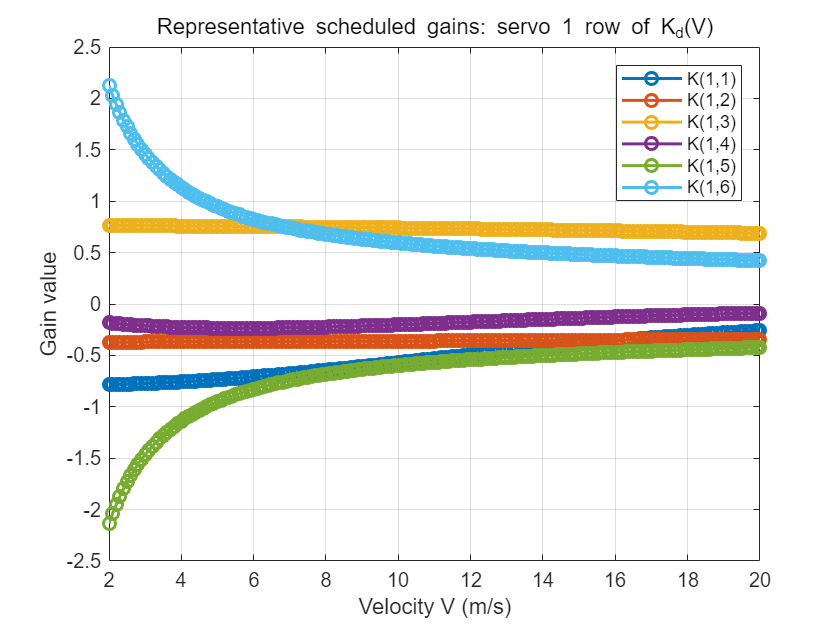


figure('Name', 'Dart LQR Gain Schedule', 'Color', 'w');
plot(V_schedule_ac, squeeze(K_d_schedule(1,1,:)), 'o-', 'LineWidth', 1.5);
hold on
plot(V_schedule_ac, squeeze(K_d_schedule(1,2,:)), 'o-', 'LineWidth', 1.5);
plot(V_schedule_ac, squeeze(K_d_schedule(1,3,:)), 'o-', 'LineWidth', 1.5);
plot(V_schedule_ac, squeeze(K_d_schedule(1,4,:)), 'o-', 'LineWidth', 1.5);
plot(V_schedule_ac, squeeze(K_d_schedule(1,5,:)), 'o-', 'LineWidth', 1.5);
plot(V_schedule_ac, squeeze(K_d_schedule(1,6,:)), 'o-', 'LineWidth', 1.5);
xlabel('Velocity V (m/s)');
ylabel('Gain value');
title('Representative scheduled gains: servo 1 row of K_d(V)');
legend('K(1,1)', 'K(1,2)', 'K(1,3)', 'K(1,4)', 'K(1,5)', 'K(1,6)', 'Location', 'best');
grid on

## Step 4: 闭环仿真验证

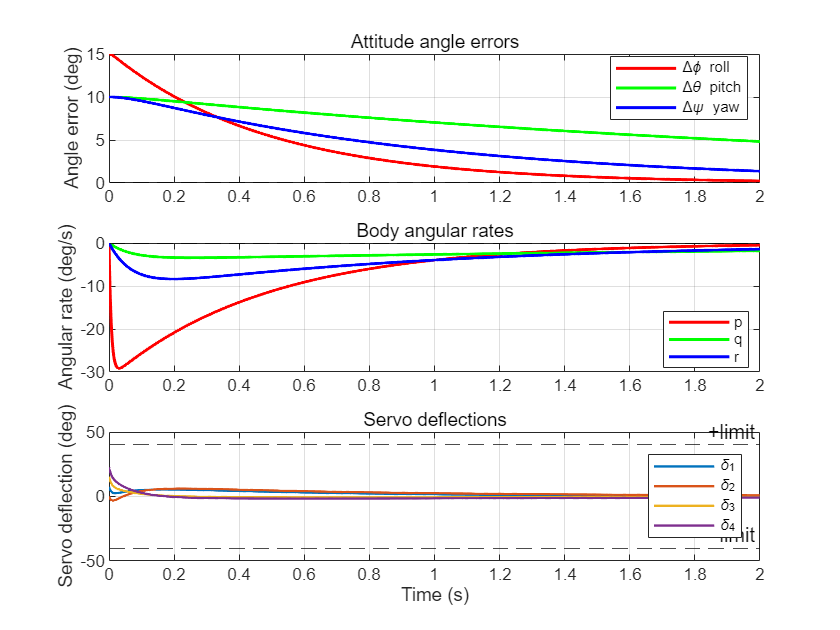

T_sim = 2.0;                       % 仿真时长，s
N = round(T_sim / Ts);             % 仿真步数

% 初始姿态扰动：roll 15 deg，pitch 10 deg，yaw 10 deg，初始角速度为 0。
x0 = [deg2rad(15);
    deg2rad(10);
    deg2rad(10);
    0;
    0;
    0];

x_hist = zeros(6, N+1);
u_hist = zeros(4, N);
x_hist(:,1) = x0;

% 离散闭环迭代：
%   u_raw = -K_d*x
%   u     = clamp(u_raw, +/-delta_max_ac)
%   x_next = A_d*x + B_d*u
%
% 本段仍使用 V_ac 对应的单点 K_d。若要仿真变速度，可把每一步的 K_d
% 换成由 K_d_schedule 线性插值得到的 K_d_now，同时 B 也要按真实 V 更新。
for k = 1:N
    u_raw = -K_d * x_hist(:,k);
    u = min(max(u_raw, -delta_max_ac), delta_max_ac);

    u_hist(:,k) = u;
    x_hist(:,k+1) = A_d * x_hist(:,k) + B_d * u;
end

t = (0:N) * Ts;
tu = (0:N-1) * Ts;

figure('Name', 'Dart LQR Closed-loop Simulation', 'Color', 'w');

% 上图：姿态角偏差收敛曲线。
subplot(3,1,1);
plot(t, rad2deg(x_hist(1,:)), 'r', 'LineWidth', 1.5);
hold on
plot(t, rad2deg(x_hist(2,:)), 'g', 'LineWidth', 1.5);
plot(t, rad2deg(x_hist(3,:)), 'b', 'LineWidth', 1.5);
yline(0, 'k--');
ylabel('Angle error (deg)');
legend('\Delta\phi roll', '\Delta\theta pitch', '\Delta\psi yaw', 'Location', 'best');
title('Attitude angle errors');
grid on

% 中图：机体角速度。
subplot(3,1,2);
plot(t, rad2deg(x_hist(4,:)), 'r', 'LineWidth', 1.5);
hold on
plot(t, rad2deg(x_hist(5,:)), 'g', 'LineWidth', 1.5);
plot(t, rad2deg(x_hist(6,:)), 'b', 'LineWidth', 1.5);
yline(0, 'k--');
ylabel('Angular rate (deg/s)');
legend('p', 'q', 'r', 'Location', 'best');
title('Body angular rates');
grid on

% 下图：四个舵机偏转角和限位线。
subplot(3,1,3);
plot(tu, rad2deg(u_hist(1,:)), 'LineWidth', 1.2);
hold on
plot(tu, rad2deg(u_hist(2,:)), 'LineWidth', 1.2);
plot(tu, rad2deg(u_hist(3,:)), 'LineWidth', 1.2);
plot(tu, rad2deg(u_hist(4,:)), 'LineWidth', 1.2);
yline( rad2deg(delta_max_ac), 'k--', '+limit');
yline(-rad2deg(delta_max_ac), 'k--', '-limit');
ylabel('Servo deflection (deg)');
xlabel('Time (s)');
legend('\delta_1', '\delta_2', '\delta_3', '\delta_4', 'Location', 'best');
title('Servo deflections');
grid on


% 自动验收指标。
final_angle_err_deg = max(abs(rad2deg(x_hist(1:3,end))));
peak_delta_deg = max(abs(rad2deg(u_hist(:))));
limit_delta_deg = rad2deg(delta_max_ac);

fprintf('\n--- Simulation acceptance checks at V_ac = %.1f m/s ---\n', V_ac);


--- Simulation acceptance checks at V_ac = 4.0 m/s ---


fprintf('Final max attitude error = %.4f deg (should approach 0)\n', final_angle_err_deg);

Final max attitude error = 4.8263 deg (should approach 0)


fprintf('Peak servo deflection    = %.2f deg (limit %.2f deg)\n', peak_delta_deg, limit_delta_deg);

Peak servo deflection    = 22.63 deg (limit 40.00 deg)



if peak_delta_deg >= limit_delta_deg - 1e-6
    fprintf('Warning: servo deflection reaches limit. Increase R or reduce initial disturbance.\n');
else
    fprintf('Servo saturation check: OK\n');
end

Servo saturation check: OK


## Step 5: 用 matlabFunction 导出速度方程

% 这里对齐 HerKules 的导出方式：生成可被 MATLAB/代码生成工具调用的函数文件。
% 注意：K(V)、K_d(V)、A(V)、B(V)、A_d(V)、B_d(V) 都是基于 3~5 m/s、
% 0.1 m/s 采样点拟合得到的多项式方程，不是符号 Riccati 的解析闭式解。
syms V real

K_sym   = build_poly_symbolic_matrix(K_poly_coeff,   V, V_ref_ac);
K_d_sym = build_poly_symbolic_matrix(K_d_poly_coeff, V, V_ref_ac);
A_sym   = build_poly_symbolic_matrix(A_poly_coeff,   V, V_ref_ac);
B_sym   = build_poly_symbolic_matrix(B_poly_coeff,   V, V_ref_ac);
A_d_sym = build_poly_symbolic_matrix(A_d_poly_coeff, V, V_ref_ac);
B_d_sym = build_poly_symbolic_matrix(B_d_poly_coeff, V, V_ref_ac);

matlabFunction(K_sym,   'File', 'LQR_K_Dart',   'Vars', {V});
matlabFunction(K_d_sym, 'File', 'LQR_K_Dart_d', 'Vars', {V});
matlabFunction(A_sym,   'File', 'LQR_A_Dart',   'Vars', {V});
matlabFunction(B_sym,   'File', 'LQR_B_Dart',   'Vars', {V});
matlabFunction(A_d_sym, 'File', 'LQR_A_Dart_d', 'Vars', {V});
matlabFunction(B_d_sym, 'File', 'LQR_B_Dart_d', 'Vars', {V});

fprintf('\nGenerated scheduled equation files:\n');


Generated scheduled equation files:


fprintf('  LQR_K_Dart.m\n');

  LQR_K_Dart.m


fprintf('  LQR_K_Dart_d.m\n');

  LQR_K_Dart_d.m


fprintf('  LQR_A_Dart.m\n');

  LQR_A_Dart.m


fprintf('  LQR_B_Dart.m\n');

  LQR_B_Dart.m


fprintf('  LQR_A_Dart_d.m\n');

  LQR_A_Dart_d.m


fprintf('  LQR_B_Dart_d.m\n');

  LQR_B_Dart_d.m


fprintf('Valid fit range: %.1f <= V <= %.1f m/s, V_ref = %.1f m/s\n', ...
    V_schedule_ac(1), V_schedule_ac(end), V_ref_ac);

Valid fit range: 2.0 <= V <= 20.0 m/s, V_ref = 4.0 m/s



% 额外保留一个 MATLAB 字符串，方便手动复制或对拍。
print_K_d = sprintf([strjoin(repmat({'%.17g'}, 1, size(K_d, 2)), ',  ') '\n'], K_d.');

toc

历时 2.512295 秒。



function [poly_coeff, max_abs_err] = fit_matrix_schedule(matrix_schedule, V_fit_offset, poly_order)
[row_num, col_num, ~] = size(matrix_schedule);
poly_coeff = zeros(row_num, col_num, poly_order + 1);
matrix_fit = zeros(size(matrix_schedule));

for row = 1:row_num
    for col = 1:col_num
        poly_desc = polyfit(V_fit_offset, squeeze(matrix_schedule(row, col, :)).', poly_order);
        poly_coeff(row, col, :) = fliplr(poly_desc);
        matrix_fit(row, col, :) = polyval(poly_desc, V_fit_offset);
    end
end

max_abs_err = max(abs(matrix_fit(:) - matrix_schedule(:)));
end

function M_sym = build_poly_symbolic_matrix(poly_coeff, V, V_ref)
[row_num, col_num, coeff_num] = size(poly_coeff);
s = V - V_ref;
M_sym = sym(zeros(row_num, col_num));

for row = 1:row_num
    for col = 1:col_num
        value_sym = sym(0);
        for coeff_idx = 1:coeff_num
            value_sym = value_sym + poly_coeff(row, col, coeff_idx) * s^(coeff_idx - 1);
        end
        M_sym(row, col) = value_sym;
    end
end
end
%
% Step 6: 自动生成 C 代码（一键更新飞控文件）
fprintf('正在自动生成 C 代码...\n');

正在自动生成 C 代码...



% 这里的 4.0 是输入参数的示例值，与之前定义类型时一致
codegen LQR_K_Dart_d -args {4.0} -config:lib -c

代码生成成功。




% （可选）自动把生成的 .c 和 .h 复制到你的飞控工程目录
% 假设你的飞控工程在 D:\MCU_Project\imcalib\lqr_tool\
% 取消下面两行的注释即可启用自动覆盖
% copyfile('codegen\lib\LQR_K_Dart_d\LQR_K_Dart_d.c', 'D:\MCU_Project\imcalib\lqr_tool\', 'f');
% copyfile('codegen\lib\LQR_K_Dart_d\LQR_K_Dart_d.h', 'D:\MCU_Project\imcalib\lqr_tool\', 'f');

fprintf('C 代码生成完成！\n');

C 代码生成完成！
